# **SRM Template**

close all
clearvars
clc

skew = @(x) [  0  ,-x(3), x(2);
              x(3),  0  ,-x(1);
             -x(2), x(1),  0 ];

## Symbolic variables

All the required symbolic variables for the tasks are given here. **Do not modifiy** this cell.

syms q1 q2 real

syms alpha1 a1 d1 real
syms alpha2 a2 d2 real

syms l1 lc1 l2 lc2 h1 delta dq1 dq2 ddq1 ddq2 g real % other parameters are real numbers

syms I1xx I1xy I1xz I1yy I1yz I1zz real
syms I2xx I2xy I2xz I2yy I2yz I2zz real

% Inertial parameters
% Masses
syms m1 m2 positive 

% First moments of mass
syms mX1 mY1 mZ1 real
syms mX2 mY2 mZ2 real

% Inertial matrices
syms XX1 YY1 ZZ1 positive
syms XY1 XZ1 YZ1 real
syms XX2 YY2 ZZ2 positive
syms XY2 XZ2 YZ2 real

assume(I1xx >= 0)
assume(I1yy >= 0)
assume(I1zz >= 0)

assume(I2xx >= 0)
assume(I2yy >= 0)
assume(I2zz >= 0)

syms theta1(t) theta2(t) dtheta1(t) dtheta2(t)

% Inertias defined at the CoM of the links in a frame with the same
% orientation of the joint frame

I1 = [I1xx I1xy I1xz;
      I1xy I1yy I1yz;
      I1xz I1yz I1zz];
  
I2 = [I2xx I2xy I2xz;
      I2xy I2yy I2yz;
      I2xz I2yz I2zz];

% Inertias w.r.t. the joint frame
% J1 = [XX1 XY1 XZ1;
%       XY1 YY1 YZ1;
%       XZ1 YZ1 ZZ1];

% J2 = [XX2 XY2 XZ2;
%       XY2 YY2 YZ2;
%       XZ2 YZ2 ZZ2];

% First moment of mass vectors
% s_1 = [mX1 mY1 mZ1]';
% s_2 = [mX2 mY2 mZ2]';  
  
% Inertial parameter vectors
% X1 = [XX1 XY1 XZ1 YY1 YZ1 ZZ1 mX1 mY1 mZ1 m1]';
% X2 = [XX2 XY2 XZ2 YY2 YZ2 ZZ2 mX2 mY2 mZ2 m2]';

% First moment of mass vectors
% s_1 = [mX1 mY1 mZ1]';
% s_2 = [mX2 mY2 mZ2]';  
  
% Inertial parameter vectors
% X1 = [XX1 XY1 XZ1 YY1 YZ1 ZZ1 mX1 mY1 mZ1 m1]';
% X2 = [XX2 XY2 XZ2 YY2 YZ2 ZZ2 mX2 mY2 mZ2 m2]';
% X  = [X1; X2];

disp('Symbolic variables defined');

Symbolic variables defined


# TASK 1

## Get the MDH parameters of the double pendulum in the figure below

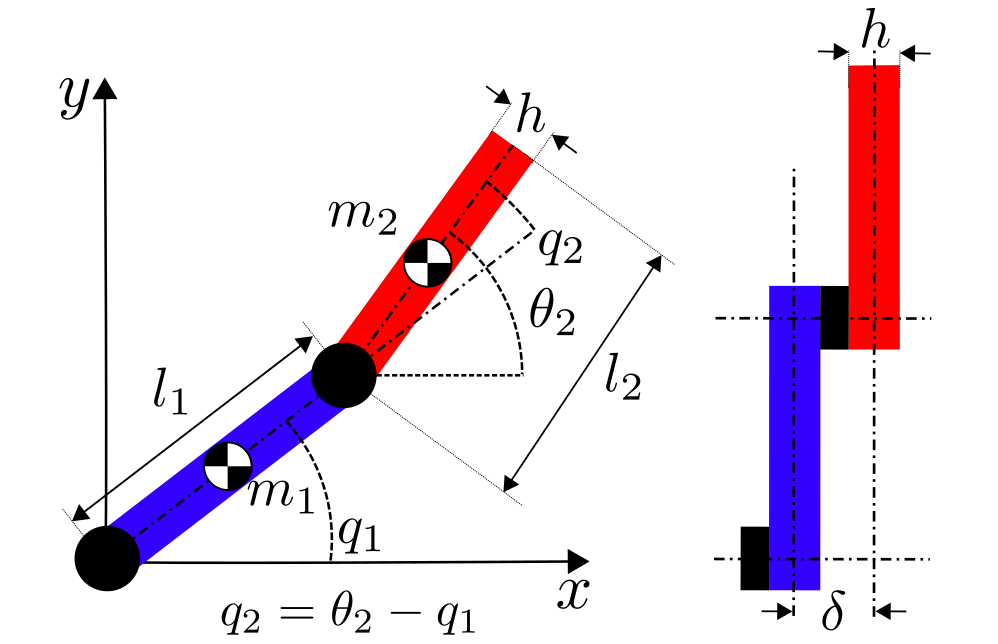

Parameters for the first link

a1      = 0; % <YOUR_CODE_HERE>
d1      = 0; % <YOUR_CODE_HERE>
alpha1  = 0; % <YOUR_CODE_HERE>
theta_1 = q1; % <YOUR_CODE_HERE>

Parameters for the second link

a2      = l1; % <YOUR_CODE_HERE>
d2      = delta; % <YOUR_CODE_HERE>
alpha2  = 0; % <YOUR_CODE_HERE>
theta_2 = q2; % <YOUR_CODE_HERE>

# TASK 2

## Find the homogeneous transformation matrices $$^0\mathbf{T}_1$$ and $$^1\mathbf{T}_2$$ and the center of mass Jacobians

### Kinematic terms: define here the corresponding rotation matrices, transformation matrices, and Jacobians.

Rotation matrices around x-axis

Rx_alpha1 = [1 0 0;0 cos(alpha1) -sin(alpha1);0 sin(alpha1) cos(alpha1)]; % <YOUR_CODE_HERE>
Rx_alpha2 = [1 0 0;0 cos(alpha2) -sin(alpha2);0 sin(alpha2) cos(alpha2)]; % <YOUR_CODE_HERE>

Rotation matrices around z-axis

Rz1   = [cos(q1) -sin(q1) 0;sin(q1) cos(q1) 0;0 0 1];% <YOUR_CODE_HERE>
Rz2   = [cos(q2) -sin(q2) 0;sin(q2) cos(q2) 0;0 0 1]; % <YOUR_CODE_HERE>  

Rotation matrices between frames

R_0_1 = Rx_alpha1*Rz1; % <YOUR_CODE_HERE>
R_1_2 = Rx_alpha2*Rz2; % <YOUR_CODE_HERE>
R_0_2 = R_0_1*R_1_2; % <YOUR_CODE_HERE>

Homogeneous transformation matrices

% Pure rotation
T_rot_x_alpha_1 = [1 0 0 0;0 cos(alpha1) -sin(alpha1) 0; 0 sin(alpha1) cos(alpha1) 0; 0 0 0 1]; % <YOUR_CODE_HERE>
% Pure translation
T_trans_x_a_1   = [1 0 0 a1;0 1 0 0;0 0 1 0;0 0 0 1]; % <YOUR_CODE_HERE>
% Pure rotaion
T_rot_z_q_1     = [cos(q1) -sin(q1) 0 0;sin(q1) cos(q1) 0 0;0 0 1 0;0 0 0 1]; % <YOUR_CODE_HERE>
% Pure translation
T_trans_z_a_1   = [1 0 0 0;0 1 0 0;0 0 1 d1;0 0 0 1]; % <YOUR_CODE_HERE>

% Pure rotation
T_rot_x_alpha_2 = [1 0 0 0;0 cos(alpha2) -sin(alpha2) 0; 0 sin(alpha2) cos(alpha2) 0; 0 0 0 1]; % <YOUR_CODE_HERE>
% Pure translation
T_trans_x_a_2   = [1 0 0 a2;0 1 0 0;0 0 1 0;0 0 0 1]; % <YOUR_CODE_HERE>
% Pure rotaion
T_rot_z_q_2     = [cos(q2) -sin(q2) 0 0;sin(q2) cos(q2) 0 0;0 0 1 0;0 0 0 1]; % <YOUR_CODE_HERE>
% Pure translation
T_trans_z_a_2   = [1 0 0 0;0 1 0 0;0 0 1 d2;0 0 0 1]; % <YOUR_CODE_HERE>

Transformation matrices between frames (USE the "simplify" command to get easy-to-read outputs)

T_0_1 = T_rot_x_alpha_1*T_trans_x_a_1*T_rot_z_q_1*T_trans_z_a_1; % <YOUR_CODE_HERE>
T_1_2 = T_rot_x_alpha_2*T_trans_x_a_2*T_rot_z_q_2*T_trans_z_a_2; % <YOUR_CODE_HERE>

T_0_2 = simplify(T_0_1*T_1_2); % <YOUR_CODE_HERE>

Jacobians for the centers of mass

T_1_1com = [1 0 0 lc1;0 1 0 0;0 0 1 0;0 0 0 1]; % <YOUR_CODE_HERE>
T_0_1com = simplify(T_0_1*T_1_1com) % <YOUR_CODE_HERE>

$$T\_0\_1com = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & {\mathrm{lc}}_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & {\mathrm{lc}}_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_2_2com = [1 0 0 lc2;0 1 0 0;0 0 1 0;0 0 0 1]; % <YOUR_CODE_HERE>
T_0_2com = simplify(T_0_2*T_2_2com) % <YOUR_CODE_HERE>

$$T\_0\_2com = \left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right) & 0 & {\mathrm{lc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & 0 & {\mathrm{lc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & \delta \\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_2_EE = [1 0 0 l2;0 1 0 0;0 0 1 0;0 0 0 1]; % <YOUR_CODE_HERE>
T_0_EE = simplify(T_0_2*T_2_EE); % <YOUR_CODE_HERE>

p_0_1com = [lc1*cos(q1);lc1*sin(q1);0]; % <YOUR_CODE_HERE>
p_0_2com = [l1*cos(q1)+lc2*cos(q1+q2);l1*sin(q1)+lc2*sin(q1+q2);delta]; % <YOUR_CODE_HERE>

J_0_v1com = [diff(p_0_1com(1),q1),diff(p_0_1com(1),q2);
             diff(p_0_1com(2),q1),diff(p_0_1com(2),q2);
             0,0]; % <YOUR_CODE_HERE>
J_0_w1com = [0,0;
             0,0;
             1,0]; % <YOUR_CODE_HERE>

J_0_v2com = [diff(p_0_2com(1),q1),diff(p_0_2com(1),q2);
             diff(p_0_2com(2),q1),diff(p_0_2com(2),q2);
             0,0] % <YOUR_CODE_HERE>

$$J\_0\_v2com = \left(\begin{array}{cc} -{\mathrm{lc}}_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right) & -{\mathrm{lc}}_{2}\,\sin\left(q_{1}+q_{2}\right)\\ {\mathrm{lc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & {\mathrm{lc}}_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & 0 \end{array}\right)$$

J_0_w2com = [0,0;
             0,0;
             1,1] % <YOUR_CODE_HERE>

J_0_w2com =      0     0
     0     0
     1     1


         
J1=[J_0_v1com;J_0_w1com]

$$J1 = \left(\begin{array}{cc} -{\mathrm{lc}}_{1}\,\sin\left(q_{1}\right) & 0\\ {\mathrm{lc}}_{1}\,\cos\left(q_{1}\right) & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 1 & 0 \end{array}\right)$$

J2=[J_0_v2com;J_0_w2com]

$$J2 = \left(\begin{array}{cc} -{\mathrm{lc}}_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right) & -{\mathrm{lc}}_{2}\,\sin\left(q_{1}+q_{2}\right)\\ {\mathrm{lc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & {\mathrm{lc}}_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 1 & 1 \end{array}\right)$$

# TASK 3

## Get the forward dynamics model of the double-pendulum using the Lagrangian method and the Symbolic Toolbox

Compute the mass matrix

% Joint angle time derivatives
dq = [dq1; dq2];

M  = simplify(m1*(J_0_v1com'*J_0_v1com)+J_0_w1com'*R_0_1*I1*R_0_1'*J_0_w1com+...
              m2*(J_0_v2com'*J_0_v2com)+J_0_w2com'*R_0_2*I2*R_0_2'*J_0_w2com) % <YOUR_CODE_HERE>

$$M = \left(\begin{array}{cc} m_{2}\,{l_{1}}^{2}+2\,m_{2}\,\cos\left(q_{2}\right)\,l_{1}\,{\mathrm{lc}}_{2}+m_{1}\,{{\mathrm{lc}}_{1}}^{2}+m_{2}\,{{\mathrm{lc}}_{2}}^{2}+\mathrm{I1zz}+\mathrm{I2zz} & m_{2}\,{{\mathrm{lc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{lc}}_{2}+\mathrm{I2zz}\\ m_{2}\,{{\mathrm{lc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{lc}}_{2}+\mathrm{I2zz} & m_{2}\,{{\mathrm{lc}}_{2}}^{2}+\mathrm{I2zz} \end{array}\right)$$

Kinetic energy: $T=\frac{1}{2}\dot{\mathbf{q}}^T\mathbf{M}\dot{\mathbf{q}}$

T  = simplify(1/2*dq'*M*dq) % <YOUR_CODE_HERE>

$$T = \begin{array}{l} {\mathrm{dq}}_{1}\,\left(\frac{{\mathrm{dq}}_{2}\,\sigma_{1}}{2}+\frac{{\mathrm{dq}}_{1}\,\left(m_{2}\,{l_{1}}^{2}+2\,m_{2}\,\cos\left(q_{2}\right)\,l_{1}\,{\mathrm{lc}}_{2}+m_{1}\,{{\mathrm{lc}}_{1}}^{2}+m_{2}\,{{\mathrm{lc}}_{2}}^{2}+\mathrm{I1zz}+\mathrm{I2zz}\right)}{2}\right)+{\mathrm{dq}}_{2}\,\left(\frac{{\mathrm{dq}}_{2}\,\left(m_{2}\,{{\mathrm{lc}}_{2}}^{2}+\mathrm{I2zz}\right)}{2}+\frac{{\mathrm{dq}}_{1}\,\sigma_{1}}{2}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,{{\mathrm{lc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{lc}}_{2}+\mathrm{I2zz} \end{array}$$

Potential energy: V = U1 + U2

U1 = m1*g*lc1*sin(q1); % <YOUR_CODE_HERE>
U2 = m2*g*(l1*sin(q1)+lc2*sin(q1+q2)); % <YOUR_CODE_HERE>
U  = U1+U2

$$U = g\,m_{2}\,\left({\mathrm{lc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)+g\,{\mathrm{lc}}_{1}\,m_{1}\,\sin\left(q_{1}\right)$$

Coriolis matrix

g111  = 1/2*(diff(M(1,1),q1)+diff(M(1,1),q1)-diff(M(1,1),q1));
g112  = 1/2*(diff(M(1,1),q2)+diff(M(1,2),q1)-diff(M(1,2),q1));
g121  = 1/2*(diff(M(1,2),q1)+diff(M(1,1),q2)-diff(M(2,1),q1));
g122  = 1/2*(diff(M(1,2),q2)+diff(M(1,2),q2)-diff(M(2,2),q1));
g211  = 1/2*(diff(M(2,1),q1)+diff(M(2,1),q1)-diff(M(1,1),q2));
g212  = 1/2*(diff(M(2,1),q2)+diff(M(2,2),q1)-diff(M(1,2),q2));
g221  = 1/2*(diff(M(2,2),q1)+diff(M(2,1),q2)-diff(M(2,1),q2));
g222  = 1/2*(diff(M(2,2),q2)+diff(M(2,2),q2)-diff(M(2,2),q2));
C11   = g111*dq1+g112*dq2;
C12   = g121*dq1+g122*dq2;
C21   = g211*dq1+g212*dq2;
C22   = g221*dq1+g222*dq2;
C     = [C11,C12;C21,C22]

$$C = \left(\begin{array}{cc} -{\mathrm{dq}}_{2}\,l_{1}\,{\mathrm{lc}}_{2}\,m_{2}\,\sin\left(q_{2}\right) & -{\mathrm{dq}}_{1}\,l_{1}\,{\mathrm{lc}}_{2}\,m_{2}\,\sin\left(q_{2}\right)-{\mathrm{dq}}_{2}\,l_{1}\,{\mathrm{lc}}_{2}\,m_{2}\,\sin\left(q_{2}\right)\\ {\mathrm{dq}}_{1}\,l_{1}\,{\mathrm{lc}}_{2}\,m_{2}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$

M_aux = subs(M,[q1 q2],[theta1 theta2]);
dM_aux = diff(M_aux,t);
dM = subs(dM_aux,[theta1 theta2 diff(theta1(t),t) diff(theta2(t),t)],[q1 q2 dq1 dq2]);% <YOUR_CODE_HERE

Gravity vector

G = [diff(U,q1);diff(U,q2)] % <YOUR_CODE_HERE>

$$G = \left(\begin{array}{c} g\,m_{2}\,\left({\mathrm{lc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)+g\,{\mathrm{lc}}_{1}\,m_{1}\,\cos\left(q_{1}\right)\\ g\,{\mathrm{lc}}_{2}\,m_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

## Verify that the properties in 2.4.5 from the script are satisfied

if sum(sum(double(simplify(M - M')))) ~= 0
    error('Your mass matrix is NOT symmetric!!!')
else
    fprintf('Great! Your mass matrix is symmetric.')
end

Great! Your mass matrix is symmetric.

if double(simplify(dq'*(dM - 2*C)*dq)) ~= 0
    error('The skew-symmetric property was not satisfied!') 
else
    fprintf('Coriolis matrix skew-symmetry property test passed!')
end

Coriolis matrix skew-symmetry property test passed!

# TASK 4

## Use Simulink to simulate the motion of the double pendulum using the found dynamics

Assign values to (symbolic) variables

m1    = 1;
m2    = 1;
l1    = 1; 
lc1   = l1/2 ;
l2    = 1;
lc2   = l2/2;
h1    = 0.1;
delta = 0.05;
g     = 9.81;

Compute the expressions for the inertia tensors w.r.t. the links' center of mass

I_com1 = m1/12*[(l1^2+h1^2) 0 0;0 (l1^2+l1^2) 0;0 0 (h1^2+l1^2)]; % <YOUR_CODE_HERE>
I_com2 = m2/12*[(l1^2+h1^2) 0 0;0 (l2^2+l2^2) 0;0 0 (h1^2+l2^2)]; % <YOUR_CODE_HERE>

[I1xx, I1xy, I1xz, I1yy, I1yz, I1zz] = deal(I_com1(1,1),I_com1(1,2),I_com1(1,3),I_com1(2,2),I_com1(2,3),I_com1(3,3));
[I2xx, I2xy, I2xz, I2yy, I2yz, I2zz] = deal(I_com2(1,1),I_com2(1,2),I_com2(1,3),I_com2(2,2),I_com2(2,3),I_com2(3,3));

Compute the expressions for the inertia tensors w.r.t. the links' frames

J1 = I_com1 - m1*skew([lc1 0 0])*skew([lc1 0 0]);
J2 = I_com2 - m2*skew([lc2 0 0])*skew([lc2 0 0]);

[XX1, XY1, XZ1, YY1, YZ1, ZZ1] = deal(J1(1,1),J1(1,2),J1(1,3),J1(2,2),J1(2,3),J1(3,3));
[XX2, XY2, XZ2, YY2, YZ2, ZZ2] = deal(J2(1,1),J2(1,2),J2(1,3),J2(2,2),J2(2,3),J2(3,3));

First moments of mass

mX1 = m1*lc1;
mY1 = 0;
mZ1 = 0;
mX2 = m2*lc2;
mY2 = 0;
mZ2 = 0; 

The code below will generate the required Simulink function blocks **based on your expressions**, you should get blocks that depend only on the joint position and/or velocity

new_system('my_system')

open_system('my_system')

matlabFunctionBlock('my_system/M_matrix', subs(M),'Outputs', {'M'})
matlabFunctionBlock('my_system/C_matrix', subs(C),'Outputs', {'C'})
matlabFunctionBlock('my_system/G_matrix', subs(G),'Outputs', {'G'})
matlabFunctionBlock('my_system/Kinetic', subs(T),'Outputs', {'T'})
matlabFunctionBlock('my_system/Potential', subs(U),'Outputs', {'U'})

# Compare against the Robotics System Toolbox results

Make sure your modified DH parameters are correct and run this section

twoLinkRobot = rigidBodyTree;

% first link properties
link1 = rigidBody('link1');
link1.Mass = m1;
link1.CenterOfMass = [lc1, 0, 0];
link1.Inertia = [XX1, YY1, ZZ1, YZ1, XZ1, XY1];
joint1 = rigidBodyJoint('joint1','revolute');
joint1.HomePosition = 0;
setFixedTransform(joint1,[a1, alpha1, d1, 0],'mdh')
link1.Joint = joint1;
addBody(twoLinkRobot, link1,'base');

% second link properties
link2 = rigidBody('link2');
link2.Mass = m2;
link2.CenterOfMass = [lc2, 0, 0];
link2.Inertia = [XX2, YY2, ZZ2, YZ2, XZ2, XY2];
joint2 = rigidBodyJoint('joint2','revolute');
joint2.HomePosition = 0;
setFixedTransform(joint2, double(subs([a2, alpha2, d2, 0])), 'mdh');
link2.Joint = joint2;
addBody(twoLinkRobot, link2, 'link1'); % Add body2 to body1

twoLinkRobot.Gravity = [0; -g; 0];
twoLinkRobot.DataFormat = 'column';

% Set direction of gravity vector (given in base -- world -- frame)
twoLinkRobot.Gravity = [0; -g; 0];
% Set format for joint and velocity argument vectors
twoLinkRobot.DataFormat = 'column';

% Functions to numerically evaluate the symbolic expressions computed in
% the previous cells
getMass     = @(M,q) double(subs(subs(M), [q1, q2], [q(1), q(2)]));
getCoriolis = @(C, q, dq) double(subs(subs(C), [q1, q2, dq1, dq2], [q(1), q(2), dq(1), dq(2)]));
getGravity  = @(G,q) double(subs(subs(G), [q1, q2], [q(1), q(2)]));
